clc;clearvars;close all;
global DOFS; 
DOFS = [true,true,true];
E = 2e4; L = 100; h = 75;
I1 = 550.98; A1 = 11.75; Aeq1 = 3.84; d=12;
A2 = 4.9; p = 0.24;
n1 = NODES(1,0  ,0 ,"constraint" ,"fixed",dy=-0.1,dRz = -deg2rad(2));
n2 = NODES(2,L  ,0 ,fy=-250,m=-400,constraint="hroller");
n3 = NODES(3,0  ,-h,constraint = "fixed",dy=-0.1,dRz = deg2rad(2));
cr1 = tempcross(E,A1,I=I1,Aeq=Aeq1,d=d);
cr2 = tempcross(E,A2);
m1 = member(n1,n2,cr1,"alpha",12e-6,"Tu",40,"Tl",20);
m2 = truss_member(n2,n3,cr2,pre=0.2);
L1 = rec(m1,0,L,p,"down","g");

## Automatically creating the cell matrices and running the final solver

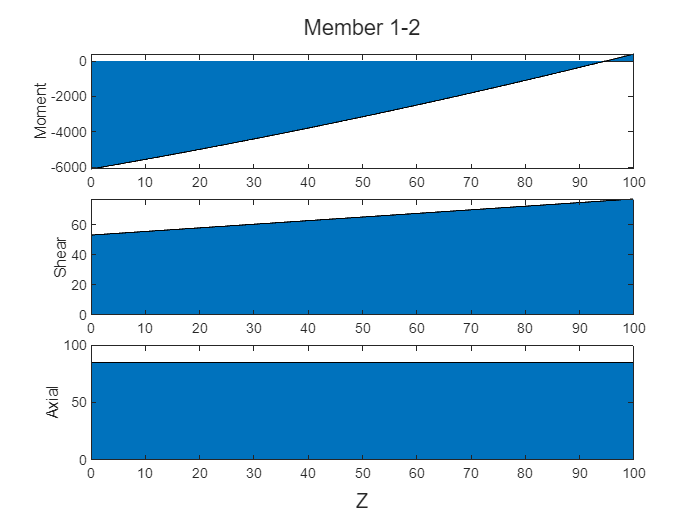

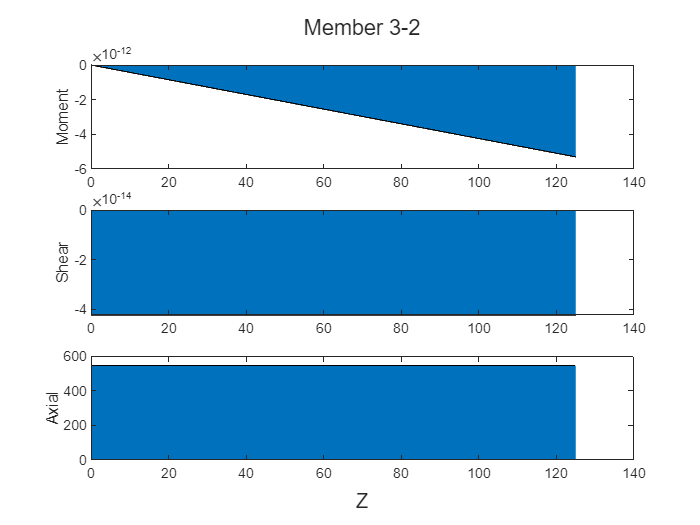

Deflections:
   -1.5922
   -0.0092

Reactions:
   1.0e+03 *

    0.0846
   -0.0531
   -6.1087
   -0.5207
    0.4361
    0.3271
         0




members = {};
nodes = {};
loads = {};
j = evalin('base','who');
for n = 1:length(j)
    r = evalin('base',j{n});
    if isa(r,'member') || isa(r,'truss_member')
        members = {members{:},r};
    elseif isa(r,'NODES')
        nodes = {nodes{:},r};
    elseif isa(r,'con_fm')||isa(r,'con_m')||isa(r,'n_tri')||isa(r,'rec')||isa(r,'rev_tri')
        loads = {loads{:},r};
    end
end
[Ar,D,Df,members] = final_solver(members,nodes,loads);